A = [-1 0 2;
     3 -2 7;
     1 2 5];

eig_open = eig(A);
disp('Собственные числа открытой системы:');

Собственные числа открытой системы:


disp(eig_open');

    6.9777   -1.8093   -3.1683




k_star = -max(real(eig_open));
fprintf('k* ≈ %.5f\n', k_star);

k* ≈ -6.97767



k = k_star - 1;

A_closed = A + k*eye(3);

eig_closed = eig(A_closed);
disp('Собственные числа замкнутой системы:');

Собственные числа замкнутой системы:


disp(sort(real(eig_closed))');

  -11.1460   -9.7870   -1.0000



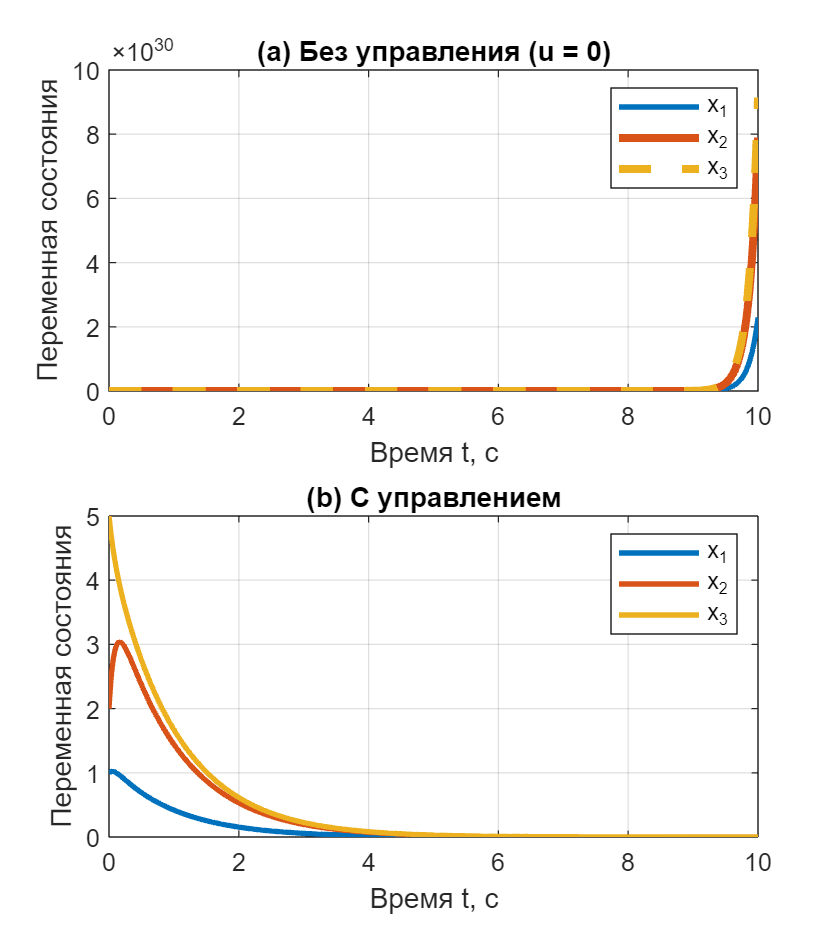


x0 = [1; 2; 5];

simtime = 10;
dt = 0.01;
t = 0:dt:simtime;

sys_open = ss(A, zeros(3,1), eye(3), 0);
sys_closed = ss(A_closed, zeros(3,1), eye(3), 0);

[x_open, t_open] = initial(sys_open, x0, t);
[x_closed, t_closed] = initial(sys_closed, x0, t);

figure('Position', [100, 100, 800, 1200]);

subplot(2,1,1);
plot(t_open, x_open(:,1), '-', 'LineWidth', 2);
hold on;
plot(t_open, x_open(:,2), '-', 'LineWidth', 3);
hold on;
plot(t_open, x_open(:,3), '--', 'LineWidth', 3);
grid on;
title('(а) Без управления (u = 0)');
xlabel('Время t, с');
ylabel('Переменная состояния');
legend('x_1', 'x_2', 'x_3');

subplot(2,1,2);
plot(t_closed, x_closed, 'LineWidth', 2);
grid on;
title('(b) С управлением');
xlabel('Время t, с');
ylabel('Переменная состояния');
legend('x_1', 'x_2', 'x_3');

saveas(gcf, '1.png');